# **Developing the Apollo Lunar Module Digital Autopilot**

"Working on the design of the Lunar Module digital autopilot was the highlight of my career as an engineer. When Neil Armstrong stepped off the LM (Lunar Module) onto the moon's surface, every engineer who contributed to the Apollo program felt a sense of pride and accomplishment. We had succeeded in our goal. We had developed technology that never existed before, and through hard work and meticulous attention to detail, we had created a system that worked flawlessly." -Richard J. Gran, [*The Apollo 11 Moon Landing: Spacecraft Design Then and Now*](https://www.mathworks.com/company/newsletters/articles/the-apollo-11-moon-landing-spacecraft-design-then-and-now.html)

This example shows how Richard and the other engineers who worked on the Apollo Lunar Module digital autopilot design team could have done it using Simulink® and Aerospace Blockset™ if they had been available in 1961.

## Model Description

Developing the autopilot in Simulink takes a fraction of the time it took for the original design of the Apollo Lunar Module autopilot.

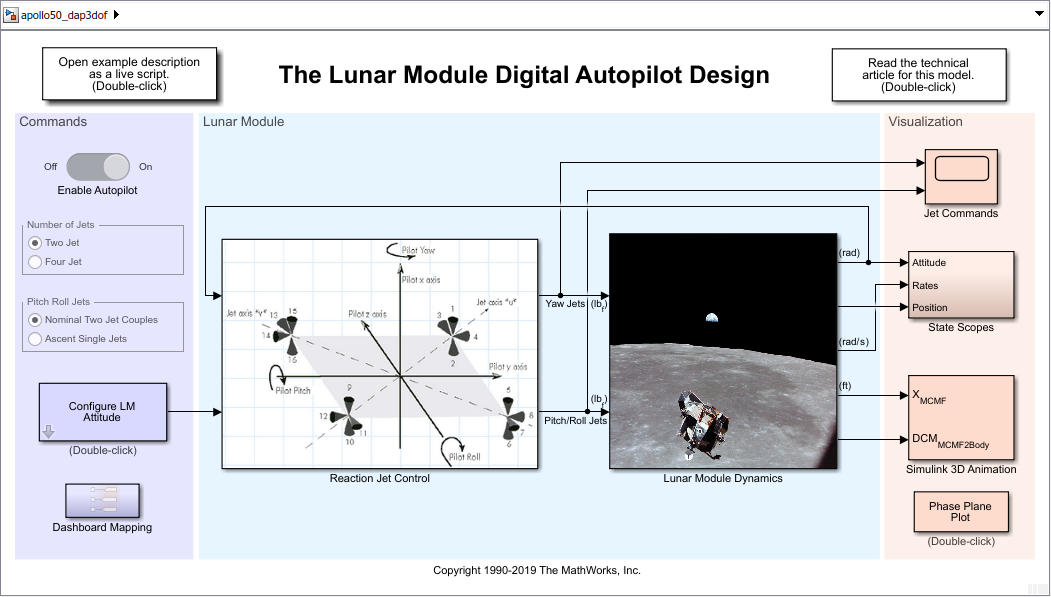

The Reaction Jet Control subsystem models the digital autopilot design proposed (and implemented) by MIT Instrumentation Laboratories (MIT IL), now called Draper Laboratory. A Stateflow® diagram in the model specifies the logic that implements the phase-plane control algorithm described in the [technical article](https://www.mathworks.com/company/newsletters/articles/the-apollo-11-moon-landing-spacecraft-design-then-and-now.html) *The Apollo 11 Moon Landing: Spacecraft Design Then and Now*. Depending on which region of the diagram the Lunar Module is executing, the Stateflow diagram is in either a `Fire_region` or a `Coast_region`. Note, the transitions between these different regions depend on certain parameters. The Stateflow diagram determines whether to transition to another state and then computes which reaction jets to fire.

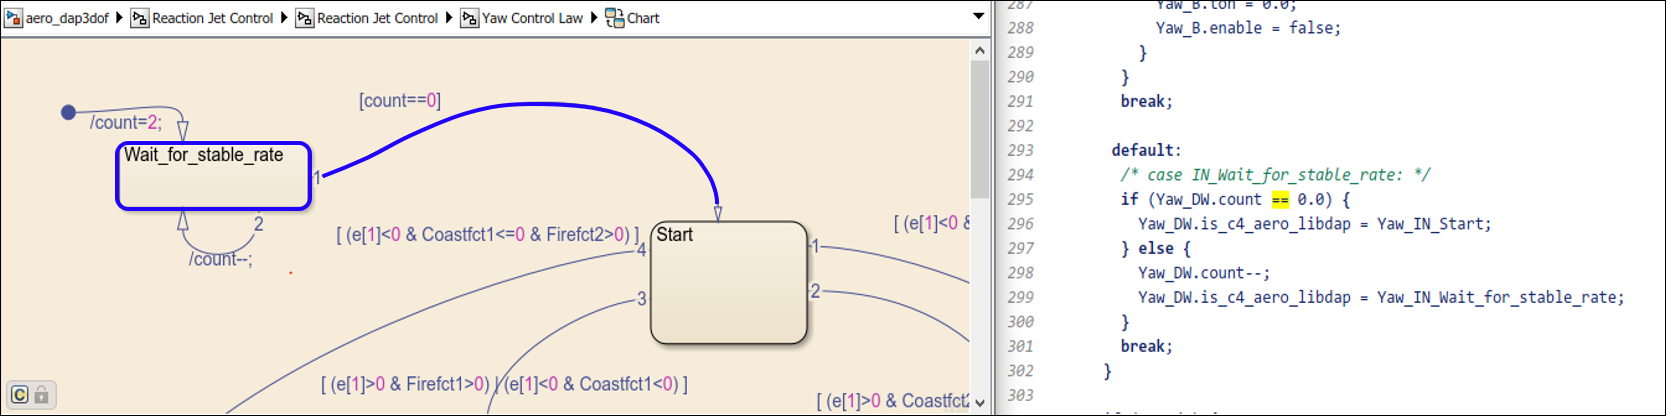

Translational and rotational dynamics of the Lunar Module are approximated in the `Lunar Module Dynamics` subsystem.  Access various visualization methods of the Lunar Module states and autopilot performance in the `Visualization` area of the model, including Simulink scopes, animation with Simulink 3D Animation, and a phase plane plot.  

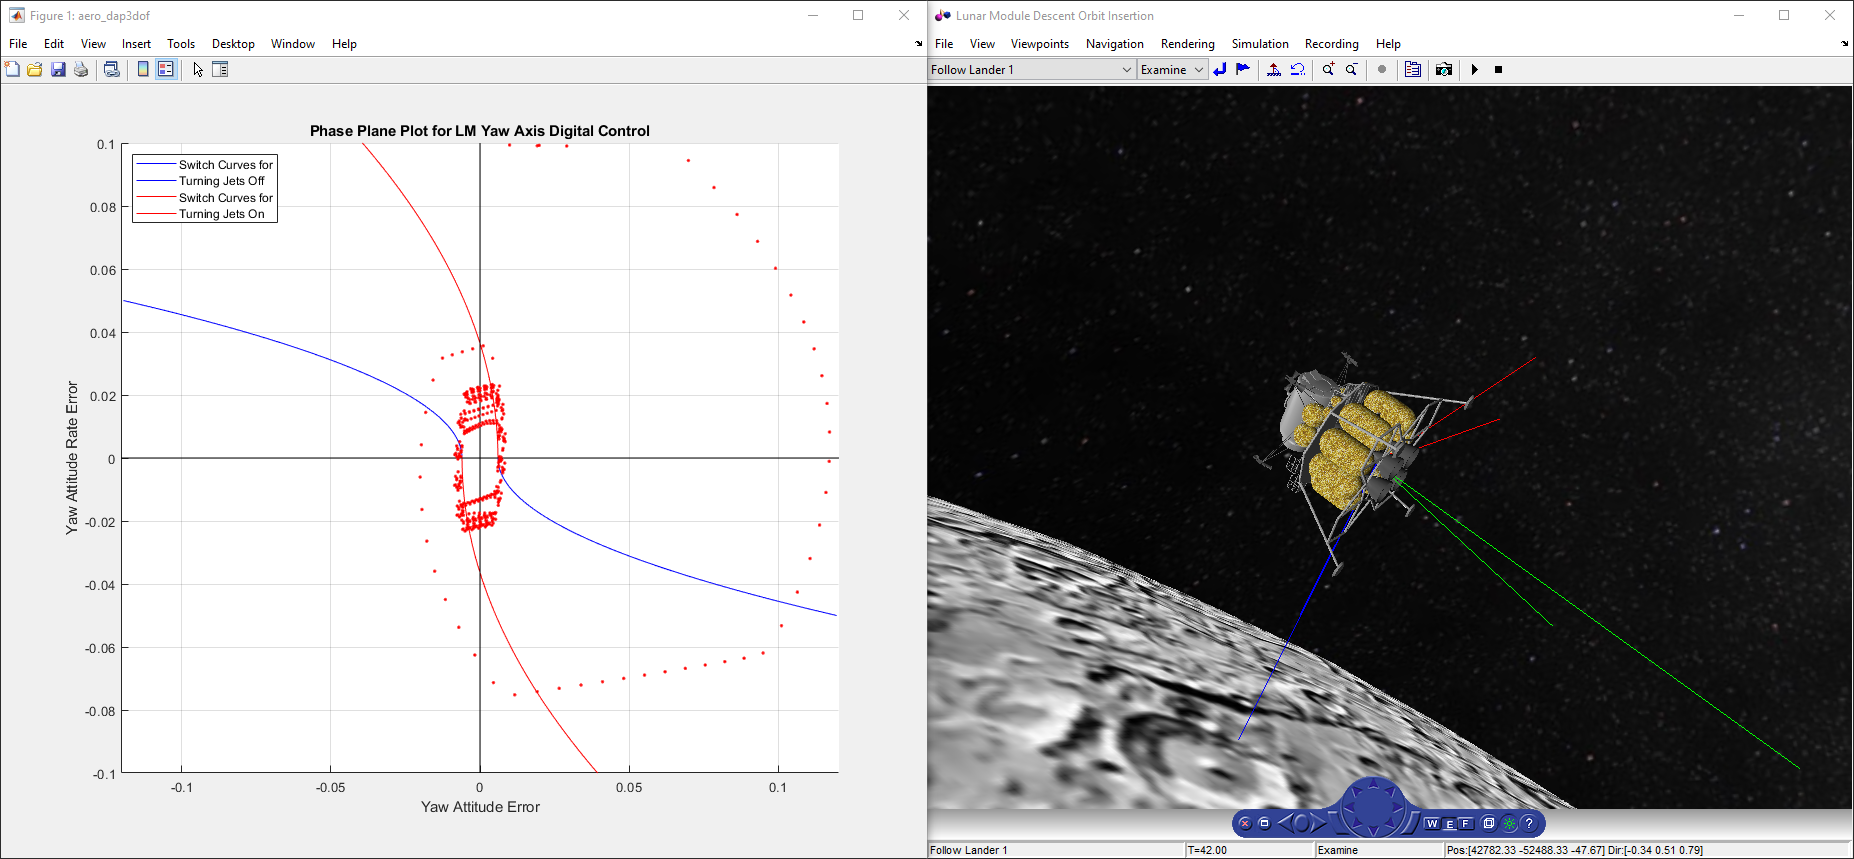

## Interactive Controls

To interact with the Lunar Module model, vary autopilot settings and Lunar Module initial states in the `Commands` area.  For example, to observe how the digital autopilot design handles increased initial body rates, use the slider components in `Configure LM Attitude`.

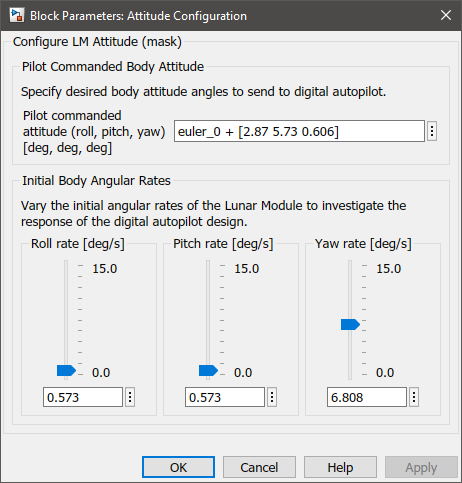

## Mission Description

The LM digital autopilot has 3 degrees of freedom. This means that by design, the reaction jet thrusters are configured and commanded to rotate the vehicle without impacting the vehicle's orbital trajectory. Therefore, the translational dynamics in his model are approximated solely via orbit propagation using the Moon Zonal Harmonic Gravity Model from Aerospace Blockset. To demonstrate the digital autopilot design behavior, the "Descent Orbit Insertion" mission segment, just prior to the initiation of the powered descent, was selected from the [*Apollo 11 Mission Report*](https://www.nasa.gov/specials/apollo50th/pdf/A11_MissionReport.pdf). 

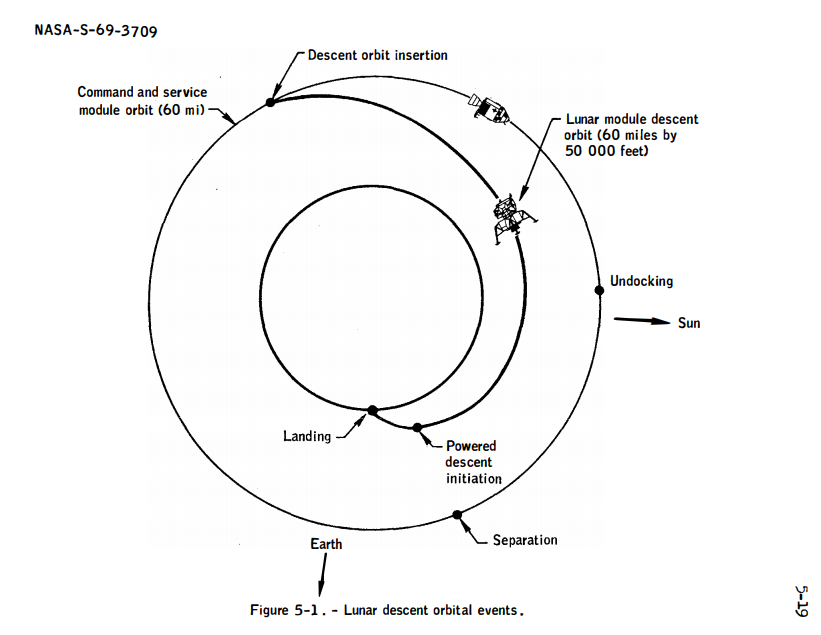 

(*Image Credit: NASA*)

The Descent Orbit Insertion burn began 101 hours, 36 minutes, and 14 seconds after lift-off and lasted 30 seconds.  The burn set the Lunar module on a trajectory to lower its orbit from approximately 60 nautical miles to 50,000 ft over about an hour.  At 50,000 ft, the Module initiated its powered descent.  

Initialize the model `apollo50_dap3dof` with the approximate trajectory of the Lunar Module immediately after the descent orbit insertion burn.

t_rangeZero             = datetime(1969,7,16,13,32,0); % lift-off
t_descentInsertionStart = t_rangeZero + hours(101) + minutes(36) + seconds(14);
t_descentInsertion      = t_descentInsertionStart + seconds(30);
t_poweredDescentStart   = t_rangeZero + hours(102) + minutes(33) + seconds(5.2);

MissionPhase = {'Range Zero (lift-off)', 'Descent Orbit Insertion (Engine ignition)', 'Descent Orbit Insertion (Engine cutoff)', 'Powered Descent (Engine ignition)'}';
MissionTime_GMT = [t_rangeZero, t_descentInsertionStart, t_descentInsertion, t_poweredDescentStart]';
disp(timetable(MissionTime_GMT, MissionPhase));

      MissionTime_GMT                      MissionPhase                
    ____________________    ___________________________________________

    16-Jul-1969 13:32:00    'Range Zero (lift-off)'                    
    20-Jul-1969 19:08:14    'Descent Orbit Insertion (Engine ignition)'
    20-Jul-1969 19:08:44    'Descent Orbit Insertion (Engine cutoff)'  
    20-Jul-1969 20:05:05    'Powered Descent (Engine ignition)'        



The trajectory of the module at Descent orbit insertion (Engine cutoff) and Powered descent initiation (Engine ignition) is provided in the [*Apollo 11 Mission Report*](https://www.nasa.gov/specials/apollo50th/pdf/A11_MissionReport.pdf) (Table 7-II.- Trajectory Parameters).

Latitude_deg  = [-1.16, 1.02]';    % [deg]
Longitude_deg = [-141.88, 39.39]'; % [deg]
Altitude_mi   = [57.8, 6.4]';      % [nautical miles] (Final measured altitude ~1.8 mi lower than projected)
Altitude_ft   = convlength(Altitude_mi, 'naut mi', 'ft');
Velocity_fps  = [5284.9, 5564.9]'; % [ft/s]
disp(table(MissionPhase(3:4), Latitude_deg, Longitude_deg, Altitude_mi, Altitude_ft, Velocity_fps));

                      Var1                       Latitude_deg    Longitude_deg    Altitude_mi    Altitude_ft    Velocity_fps
    _________________________________________    ____________    _____________    ___________    ___________    ____________

    'Descent Orbit Insertion (Engine cutoff)'       -1.16           -141.88          57.8         3.512e+05        5284.9   
    'Powered Descent (Engine ignition)'              1.02             39.39           6.4             38887        5564.9   



## Model Initialization

Initialize model parameters for the mission phase "Descent Orbit Insertion trajectory (Engine cutoff)":

run('apollo50_dap3dofdata.m');

## Closing Remarks

Building a digital autopilot was a daunting task in 1961 because there was very little industrial infrastructure for it - everything about it was in the process of being invented.  Here is an excerpt from the [technical article](https://www.mathworks.com/company/newsletters/articles/the-apollo-11-moon-landing-spacecraft-design-then-and-now.html) *The Apollo 11 Moon Landing: Spacecraft Design Then and Now*:

 "One reason why the [autopilot's machine code] was so complex is that the number of jets that could be used to control the rotations about the pilot axes was large. A decision was made to change the axes that the autopilot was controlling to the "jet axes" shown in apollo50`_dap3dof`. This change dramatically reduced the number of lines of code and made it much easier to program the autopilot in the existing computer. Without this improvement, it would have been impossible to have the autopilot use only 2000 words of storage. The lesson of this change is that when engineers are given the opportunity to code the computer with the system they are designing, they can often modify the design to greatly improve the code."

## References

[1] National Aeronautics and Space Administration Manned Spacecraft Center, Mission Evaluation Team. (November 1969). *Apollo 11 Mission Report MSC-00171*. Retrieved from [https://www.nasa.gov/specials/apollo50th/pdf/A11_MissionReport.pdf](https://www.nasa.gov/specials/apollo50th/pdf/A11_MissionReport.pdf)

[2] Richard J. Gran, MathWorks. (2019).* The Apollo 11 Moon Landing: Spacecraft Design Then and Now*. Retrieved from [https://www.mathworks.com/company/newsletters/articles/the-apollo-11-moon-landing-spacecraft-design-then-and-now.html](https://www.mathworks.com/company/newsletters/articles/the-apollo-11-moon-landing-spacecraft-design-then-and-now.html)

*Copyright 2019 The MathWorks, Inc.*